% Set the size of the matrix
rows = 6;
cols = 6;

% Set the density of non-zero elements (adjust as needed)
density = 0.4;

% Generate the random sparse matrix
M_k = sprand(rows, cols, density);

% Set the diagonal elements to non-zero values
diagonal_values = rand(rows, 1);
M_k = M_k + spdiags(diagonal_values, 0, rows, cols);

% Display the sparse matrix
disp(M_k);

   (1,1)       0.8255
   (5,1)       0.6761
   (2,2)       1.2223
   (3,2)       0.5181
   (1,3)       0.2810
   (3,3)       0.0680
   (2,4)       0.4574
   (3,4)       0.9436
   (4,4)       1.2125
   (5,4)       0.2891
   (2,5)       0.8754
   (3,5)       0.6377
   (4,5)       0.2407
   (5,5)       0.2240
   (1,6)       0.4401
   (6,6)       0.6678



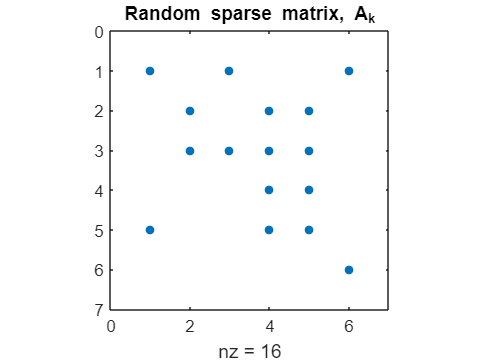

spy(M_k);
title("Random sparse matrix, A_k")

plot(digraph(M_k));
title("G(A_k)")

% Inverse of M_k
inv_M_k = inv(M_k);
disp(inv_M_k);

   (1,1)       0.3570
   (2,1)       0.9296
   (3,1)       2.5101
   (4,1)       0.2875
   (5,1)      -1.4482
   (1,2)       0.6253
   (2,2)       2.4464
   (3,2)      -1.8368
   (4,2)       0.5036
   (5,2)      -2.5367
   (1,3)      -1.4753
   (2,3)      -3.8418
   (3,3)       4.3336
   (4,3)      -1.1882
   (5,3)       5.9852
   (1,4)       0.6635
   (2,4)       2.3375
   (3,4)      -1.9491
   (4,4)       1.6432
   (5,4)      -4.1225
   (1,5)       1.0432
   (2,5)      -1.1349
   (3,5)      -3.0645
   (4,5)      -0.3510
   (5,5)       1.7681
   (1,6)      -0.2352
   (2,6)      -0.6126
   (3,6)      -1.6541
   (4,6)      -0.1895
   (5,6)       0.9543
   (6,6)       1.4974



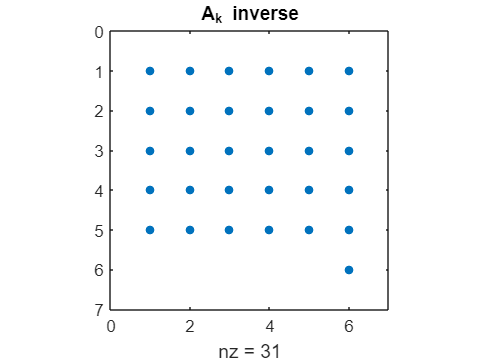

spy(inv_M_k);
title("A_k inverse")

plot(digraph(inv_M_k));
title("G*(A_k)")

% Extract the upper triangular matrix
upper_triangular_matrix = triu(M_k);

% Take the sparsity pattern
rand_upper_triangular_matrix = sprand(upper_triangular_matrix);

% Display the upper triangular matrix
disp(rand_upper_triangular_matrix);

   (1,1)       0.8444
   (2,2)       0.3445
   (1,3)       0.7805
   (3,3)       0.6753
   (2,4)       0.0067
   (3,4)       0.6022
   (4,4)       0.3868
   (2,5)       0.9160
   (3,5)       0.0012
   (4,5)       0.4624
   (5,5)       0.4243
   (1,6)       0.4609
   (6,6)       0.7702



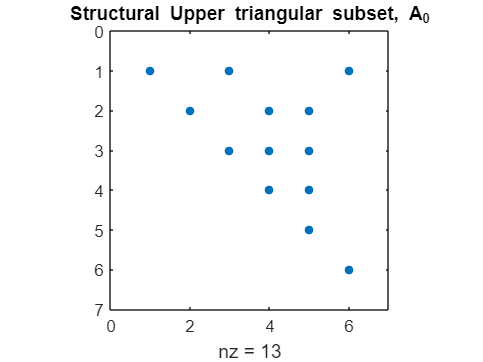

spy(rand_upper_triangular_matrix);
title("Structural Upper triangular subset, A_0")

plot(digraph(rand_upper_triangular_matrix));
title("G(A_0)")

% Preprocess SAM
[I, J] = find(rand_upper_triangular_matrix);
findJ = sparse(I,J,1);
PP = logical(findJ); % Taking the sparsity pattern of A_0
PP2 = logical(sparse(double(PP)*double(PP))); % Powers of sparsity pattern of A_0
nnzMM = nnz(PP2); % Total number of nonzero elements
rowM = zeros(2*nnzMM,1);
colM = zeros(2*nnzMM,1);
valM = zeros(2*nnzMM,1);

% Iterate over all columns of the sparsity pattern to
% store all the non-zero indices of each column of the
% Sparsity Pattern Boolean matrix
for j = 1:cols
    nz_M{j} = find(PP(:, j)); % Cell or Dictionary to save the nonzero indices of each column
    nnz_M(j) = length(nz_M{j}); % Array saving the total number of nonzero elements of each column
    nz_LS{j} = find(PP2(:,j));
    nnz_LS(j) = length(nz_LS{j});
end

max_col = max(nnz_M);
max_row = max(nnz_LS);
G = zeros(max_row,max_col);
M = zeros(max_row,1);
cntrM = 0;

% Compute SAM
for j = 1:cols
    G(1:nnz_LS(j),1:nnz_M(j)) = M_k(nz_LS{j},nz_M{j});
    M(1:nnz_M(j)) = G(1:nnz_LS(j),1:nnz_M(j))\rand_upper_triangular_matrix(nz_LS{j},j);
    rowM(cntrM+1:cntrM+nnz_M(j)) = nz_M{j};
    colM(cntrM+1:cntrM+nnz_M(j)) = j;
    valM(cntrM+1:cntrM+nnz_M(j)) = M(1:nnz_M(j));
    cntrM = cntrM+nnz_M(j);
end

 MM = sparse(rowM(1:cntrM),colM(1:cntrM),valM(1:cntrM));
 disp(MM);
 spy(MM);
 digraph(MM);
 title("Approximate Map");

% Compute Exact Map with Upper Triangular A_0
N = inv_M_k * rand_upper_triangular_matrix;
disp(N);
spy(N);
title("Exact Map - 1 (Upper triangular subset)")
plot(digraph(N));
title("G(A_k^-1 * A_0) = G(N)")